# Gradient Descent - Machine Problem 4

clear;

### TASK 1. Setting up the function to use in looking for the minimum value

Let's begin by making a 3D plot of a function. MATLAB has a default 3D image used for many 3D plotting examples. It can be invoked using the function $peaks()$. In addition, uncomment these four ways to make a 3d plot one by one. Check out the documentations for these functions in order to understand them better.

% z = peaks(100);
% surf(z)
% contour(z,16)
% surfc(z)
% mesh(z)

When you're done, comment all commands in the above field.

The 3D plotted function is based on the equation given by


$$z =  3(1-x)^2 exp[-[x^2 + (y+1)^2]] - 10(\frac{x}{5} - x^3 - y^5)exp[-(x^2+y^2)] - \frac{1}{3}exp[-[(x+1)^2 + y^2]]$$


in the domain $-3\le x\le 3$ and $-3\le y\le 3$. This is a complicated function, and it will be a pain to evaluate analytically. Thus, we are going to use symbolic MATLAB. I've already written the code to convert the function to a symbolic equation. 

syms x y z
z = @(x,y) 3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2)

z = function_handle with value:
    @(x,y)3*(1-x).^2.*exp(-(x.^2)-(y+1).^2)-10*(x/5-x.^3-y.^5).*exp(-x.^2-y.^2)-1/3*exp(-(x+1).^2-y.^2)


Test out this symbolic function by solving for the value of $z$ for any value of $x$ and $y$ within the given domain. Change the values for $x$ and $y$ in the field below. Remember to skip the semicolon to display the value.

z(-2,2)

ans = 0.0797

Using the command $linspace()$, create the vectors $x0$ and $y0$, with $n$ data points per vector. Use at least $n=100$.

x0 = linspace(-3,3,100);
y0 = linspace(-3,3,100);

Using the command $meshgrid()$, generate a 2D map of the vectors $x0$ and $y0$ that will contain $n\times n$ data points. Assign the variables $xx$ and $yy$ as the new coordinates. 

[xx,yy] = meshgrid(x0,y0);

Evaluate $z$ with the mesh $xx$ and $yy$. Assign the output of $z$ to the variable $zz$ . 

zz = z(xx,yy);

Accurately plot the result in a combined surface and contour plot. Add axes labels just to see which directions are $x$ and $y$.

Click on the figure and use the Rotate button to set a viewing angle that will allow you to estimate where the minimum value of the function is. Once you're done, click on the Update Code button. 

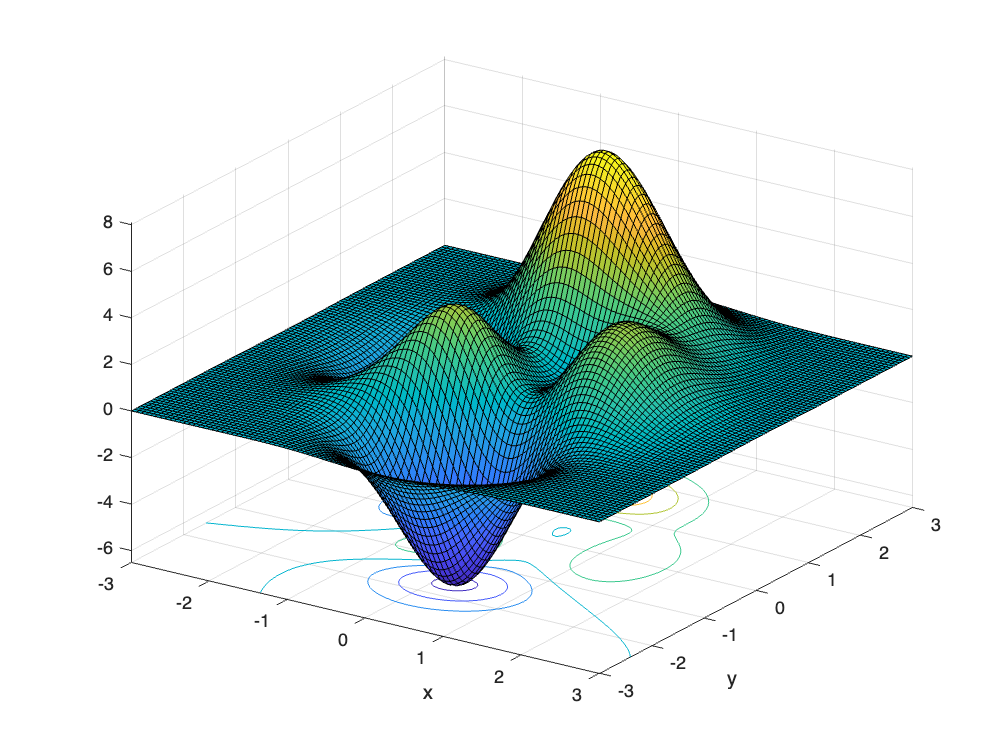

surfc(xx,yy,zz)
xlabel("x")
ylabel("y")
xlim([-3.00 3.00])
ylim([-3.00 3.00])
zlim([-6.5 8.1])
view([33.8 30.4])

We've now set up the function that we are going to use to look for its minimum value. From the graph, estimate the location of the minimum value of the plot. Write down your answer in the field below.

% minimum x:
% minimum y:

### TASK 2. Implementation of the Gradient Descent Method

In this task, you are going to put all commands in one field. It will be clearer why once you get going with the codes. Follow each step to the letter, so that you don't miss a point and make a mistake.

#### 1. Make an initial guess

As in the previous methods, you need to select a point on the graph as your initial guess. Type down your initial guess in the field below. Use the variables $xinit$ and $yinit$ as the initial guesses for the location of the minimum value of the function $z$. (Don't make it too close to your estimated value in Task 1, so that you can clearly see how Gradient Descent works.)

So that you know where your guess is and where your succeeding guesses will be, plot the function $z$ in a contour plot and add your initial guess to the plot. Use contour levels of at least 64 to make the contour lines dense and easier to see. Also, add the line $contourcbar$ so that you will be able to see a contour bar and determine the height levels better.

#### 2. Set up the differential equation

Here's the part where you will see the advantage of using symbolic math. Take another look at the equation and try to estimate how long it will take you to analytically solve for $\frac{\partial z}{\partial x}$ and $\frac{\partial z}{\partial y}$. Instead, we're going to do MATLAB do the work. 

Use the $diff()$ function to differentate $z$ with respect to both $x$ and $y$. Assign the result to the variables $dzdx$ and $dzdy$, respectively, and ensure that both these variables retain the arguments $x$ and $y$.

#### 3. Solve for the gradient vector

This is written as


$$\vec{\nabla z} =\frac{\partial z}{\partial x}\hat{i} +\frac{\partial z}{\partial y}\hat{j}$$


at your initial guesses. More specifically, compute for $\frac{\partial z}{\partial x}$ and $\frac{\partial z}{\partial y}$ at $(xinit,yinit)$. You will need to use the $double()$ function to convert the result from symbolic to numerical digits. Assign the numerical outputs to the variables $gradx$ and $grady$, respectively. 

#### 4. Define the new location

The new location would then depend on these gradient vector components. Along the x- and y-axes, these are written as

$x_{\textrm{new}} =x_{\textrm{init}} -\frac{\partial z}{\partial x}\left(h\right)$ and $y_{\textrm{new}} =y_{\textrm{init}} -\frac{\partial z}{\partial y}\left(h\right)$, 

respectively, if you want to look for the minimum values. Use the same step size as your variables $x0$ and $y0$ above. Implement these equations and assign the new x- and y-values to the variables $xnew$ and $ynew$.

#### 5. Repeat until the minimum value is found

Reassign the $xnew$ and $ynew$ variables to the initial variables $xinit$ and $init$, respectively, and repeat the process to find a new set of $xnew$ and $ynew$ coordinates. This means that you have to create a for loop. Create a $for$ loop of about 100 iterations to generate values of these new coordinates.

Remember to include only the essential lines of code in the for loop to make it as efficient as possible. Also, save each value of the gradient variables and new coordinates per iteration. This means that you also need to preallocate for these variables before the for loop to make your code efficient.

One more thing. Plot these new values per iteration so that you see if gets close to the minimum value.

#### 6. Choosing appropriate initial values

Notice that there ar at least 3 local minima. Among these these three, there is one that has the least $z$ value, and that's somewhere between 0 and 1 along the $x$ and between -2 and -1 along the $y$-axis. This is the global minimum. If you're lucky, then that means that you chose initial values that are near the global minimum value. Try out the following initial values and take a screen shot of the results (or save the figure as a *.png file) and paste it below their respective coordinates to see how important choosing the appropriate initial values are:

(0,2)

(-0.5,0.5)

(-1,-2)

If you did this correctly, you will see that with the first one, it will lead you away from any of the minima. With the second one, it leads you to a local minimum, but not the global minimum. With the third, it will lead you to the global minimum within the domain of the plot.

#### 7. Setting a tolerance value

In step 5, we set about 100 iterations. To really make your code more efficient, a tolerance value must be set. A good tolerance value is 0.01 or 1% error. But which among the variables should you compare with this tolerance value? 

Set the variable $tol$ equal to 0.01. You need to carefully think about how to incorporate this in the loop. Select the correct variable to compare the tolerance value with such that when that variable goes below the tolerance value, the loop ends.

In the matrix table below, in the second and third column, write down the coordinates of the global minimum. Write 'x' if it did not reach the global minimum. In the fourth column, write down how many iterations were necessary to get to the global minimum next to (or to the right of) their respective different initial values.


$$\left\lbrack \begin{array}{cccc}
 & x_{\textrm{opt}}  & y_{\textrm{opt}}  & \textrm{iter}\\
\left(-1,-2\right) & 0\ldotp 2285 & -1\ldotp 6263 & 15\\
\left(1,-1\right) & 0\ldotp 2285 & -1\ldotp 6263 & 25\\
\left(-0\ldotp 5,-0\ldotp 5\right) & x & x & x\\
\left(-0\ldotp 5,-0\ldotp 67\right) & 0\ldotp 2280 & -1\ldotp 6248 & 25
\end{array}\right\rbrack$$


#### 8. Step size optimization

To further make your code more efficient, an optimum value of the step size, $h$, must be chosen for each iteration. The optimum value of $h$ is mathematically obtained from the equation

$\frac{\partial f\left(x_{\textrm{init}} -\frac{\partial f}{\partial x}h,y_{\textrm{init}} -\frac{\partial f}{\partial y}h\right)}{\partial h}=0$.

Numerically, you can choose a simpler optimization method. Choose from the Random Search Method, Quadratic Interpolation Method, or the Golden Section Method, and use this to solve for the optimum value of $h$. Then use this optimum value to solve for the new x- and y-coordinates. 

In the matrix table below, in the second and third column, write down the coordinates of the global minimum. Write 'x' if it did not reach the global minimum. In the fourth column, write down how many iterations were necessary to get to the global minimum next to (or to the right of) their respective different initial values.


$$\left\lbrack \begin{array}{cccc}
 & x_{\textrm{opt}}  & y_{\textrm{opt}}  & \textrm{iter}\\
\left(-1,-2\right) & 0\ldotp 2278 & -1\ldotp 6256 & 5\\
\left(1,-1\right) & 0\ldotp 2283 & -1\ldotp 6256 & 8\\
\left(-0\ldotp 5,-0\ldotp 5\right) & x & x & x\\
\left(-0\ldotp 5,-0\ldotp 67\right) & x & x & x
\end{array}\right\rbrack$$


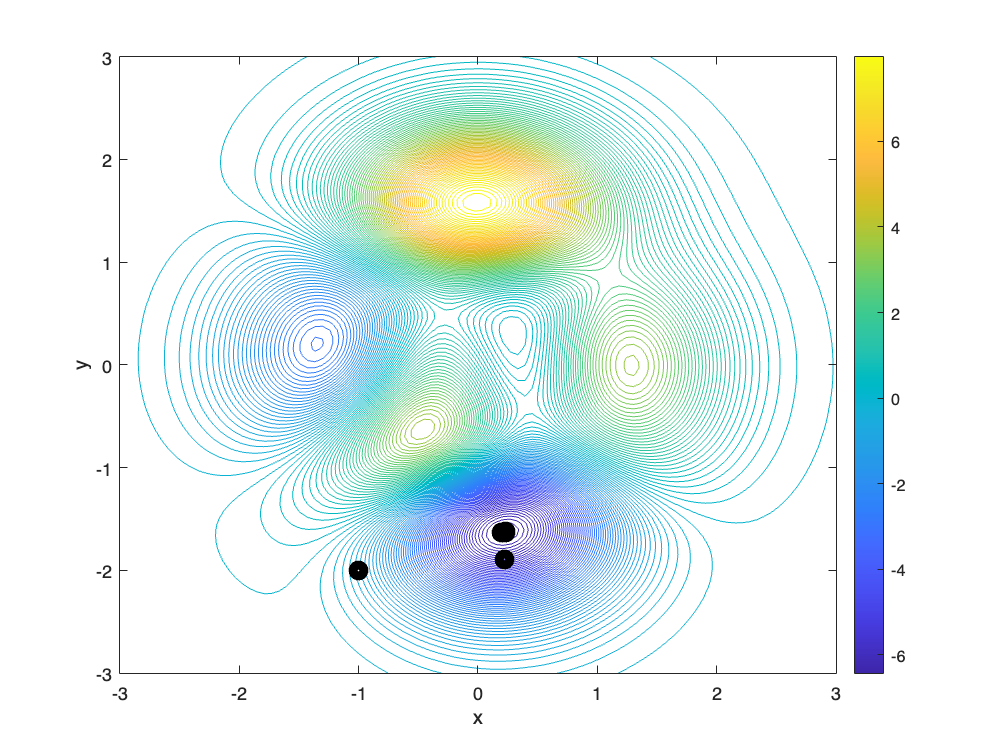

% 1
xinit = -1;
yinit = -2;
contour(xx,yy,zz,128)
contourcbar
xlabel('x')
ylabel('y')
hold on
plot(xinit,yinit,'ko',"LineWidth",5)

% 2
dzdx(x,y) = diff(z,x);
dzdy(x,y) = diff(z,y);

% 5
n = 120;
gradx = zeros(1,length(n));
grady = zeros(1,length(n));
xnew = zeros(1,length(n));
ynew = zeros(1,length(n));
h = zeros(1,length(n));
yout = zeros(1,length(n));

% 4 Define step size
% h = x0(2) - x0(1);

% 8 Define step size
h(1) = x0(2) - x0(1);

% 7
tol = 0.01;
i = 1;
temp = 100;
while(abs(temp)>tol)
    % 3
    gradx(i) = double(dzdx(xinit,yinit));
    grady(i) = double(dzdy(xinit,yinit));
    temp = gradx(i);
    
    % 8
    [h(i),yout(i),index] = randomztest(z,xinit,yinit,gradx(i),grady(i));

    % 4
    xnew(i) = xinit - gradx(i)*h(i);
    ynew(i) = yinit - grady(i)*h(i);
    
    % 5
    xinit = xnew(i);
    yinit = ynew(i);
    plot(xinit,yinit,'ko',"LineWidth",5)
    
    % 7
    i = i + 1;    
    
end

hold off

#### 9. Conclusions

State your conclusions as Text based on (1) the significance of setting an initial value, and (2) the importance of optimizing the step size. 

In the field below, display the values of the x- and y-coordinates of and the optimum value $z$ at the global minimum.

xinit

xinit = 0.2279

yinit

yinit = -1.6256

z(xinit,yinit)

ans = -6.5511

#### 10. Solution using MATLAB's built-in function

Run this section to see the answer using MATLAB's $fminsearch()$ function.

range = [-3, 3];
[sol,fmin] = fminsearch(@(x) z(x(1),x(2)),range)

sol =     0.2282   -1.6255


fmin = -6.5511

**Convert to door to door**

**Send it back to us asap**